%% Parameterize the arm
rho = 1.5 * 0.0254 / 2; % M, Radius
 
% Construct pose matrices
% Transform from world frame to base curve
g_o = SE2.hat([0, 0, pi/2]);

g_o_A = SE2.hat([0, rho, 0]);
g_o_B = SE2.hat([0, -rho, 0]);

l_0 = 0.443; % Default length

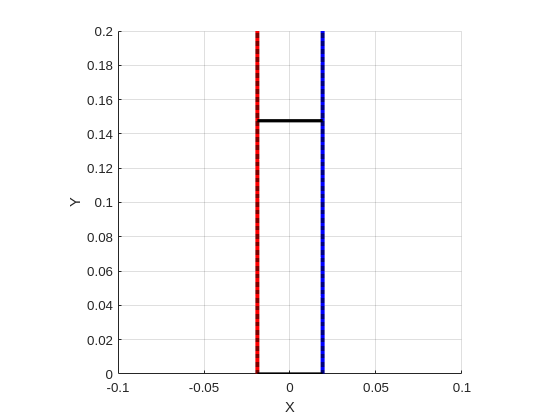

% Create arm object and initialize plotting
%planar_arm_obj = Arm2D(g_o, {g_o*g_o_A; g_o; g_o*g_o_B}, l_0, 'plot_unstrained', true);
planar_arm_obj = Arm2D(g_o, {g_o*g_o_A; g_o*g_o_B}, l_0, 'plot_unstrained', true);
planar_arm_obj.rho = rho;

fig = figure();
line_options_muscles = struct("LineWidth", 3);
line_options_spacers = struct("Linewidth", 2.5);
line_options_base_curve = struct("Linestyle", ":");

% Initialize plotting
planar_arm_obj.initialize_plotting(axes(fig), ...
    "line_options_muscles", line_options_muscles, ...
    "line_options_spacers", line_options_spacers, ...
    "line_options_base_curve", line_options_base_curve, ...
    "resolution", 40);

border_length_cm = 20;
ylim(planar_arm_obj.ax, [0, 1] * border_length_cm / 100);
xlim(planar_arm_obj.ax, [-0.5, 0.5] * border_length_cm / 100);

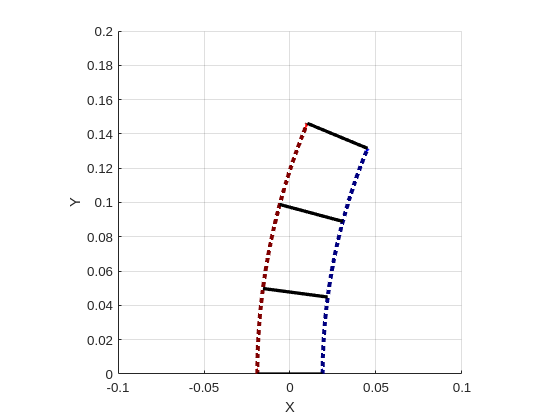

l_A = 0.15;
l_B = 0.135;
l_C = 0.1;
%v_l = [l_A; l_B; l_C];

v_l = [l_A;l_B];
planar_arm_obj.plot_unstrained = true;
planar_arm_obj.plot_base_curve = false;
planar_arm_obj.update_arm(v_l);